
%% Simulated Battery SoC Data
time = 0:10:300                           % Time vector (in seconds)

time =      0    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200   210   220   230   240   250   260   270   280   290   300


soc = linspace(100, 40, length(time))     % SoC drops linearly from 100% to 40%

soc =    100    98    96    94    92    90    88    86    84    82    80    78    76    74    72    70    68    66    64    62    60    58    56    54    52    50    48    46    44    42    40



%% 1. Find number of low SoC samples (< 60%)
num_low_soc = sum(soc < 60)

num_low_soc = 10

disp("Number of SoC samples below 60%: " + num_low_soc)

Number of SoC samples below 60%: 10



%% 2. Replace low SoC values with NaN
soc_with_nan = soc                        % Make a copy to preserve original

soc_with_nan =    100    98    96    94    92    90    88    86    84    82    80    78    76    74    72    70    68    66    64    62    60    58    56    54    52    50    48    46    44    42    40


soc_with_nan(soc_with_nan < 60) = NaN     % Mask low values

soc_with_nan =    100    98    96    94    92    90    88    86    84    82    80    78    76    74    72    70    68    66    64    62    60   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


disp("SoC with low values replaced by NaN:")

SoC with low values replaced by NaN:


disp(soc_with_nan)

   100    98    96    94    92    90    88    86    84    82    80    78    76    74    72    70    68    66    64    62    60   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN




%% 3. Show only SoC values > 80%
high_soc_values = soc(soc > 80)

high_soc_values =    100    98    96    94    92    90    88    86    84    82


disp("SoC values above 80%:")

SoC values above 80%:


disp(high_soc_values)

   100    98    96    94    92    90    88    86    84    82




%% 4. Mark index where SoC = 50% (exact match)
index_50_soc = find(soc == 50)

index_50_soc = 26

disp("Index where SoC is exactly 50%:")

Index where SoC is exactly 50%:


disp(index_50_soc)

    26




%% 5. Mask SoC values between 50% and 70%
mid_soc_values = soc(soc >= 50 & soc <= 70)

mid_soc_values =     70    68    66    64    62    60    58    56    54    52    50


disp("SoC values between 50% and 70%:")

SoC values between 50% and 70%:


disp(mid_soc_values)

    70    68    66    64    62    60    58    56    54    52    50




%% 6. Get time values where SoC < 55%
time_low_soc = time(soc < 55)

time_low_soc =    230   240   250   260   270   280   290   300


disp("Time points where SoC is below 55%:")

Time points where SoC is below 55%:


disp(time_low_soc)

   230   240   250   260   270   280   290   300



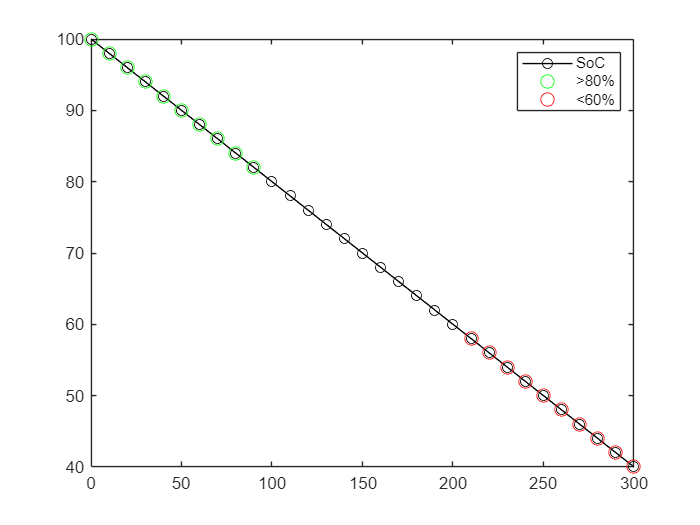

plot(time, soc, 'k-o')      % Plot original
hold on
plot(time(soc > 80), soc(soc > 80), 'go', 'MarkerSize', 8)
plot(time(soc < 60), soc(soc < 60), 'ro', 'MarkerSize', 8)
hold off
legend('SoC','>80%','<60%')